filename = "/Users/vysakhpr/Documents/Coursera/Computer Vision for Engineering and Science/Data/MathWorks Images/Roadside Ground Cover";

imageDs = imageDatastore(filename, "IncludeSubfolders", true, LabelSource="foldernames");

[trainDs, testDs] = splitEachLabel(imageDs, 0.85, "randomized");

names = [];
meansat = [];
stdsat = [];

while hasdata(trainDs)
    [img, info] = read(trainDs);
    imghsv = rgb2hsv(img);
    imgsat = imghsv(:,:,2);
    
    [~,name,ext] = fileparts(info.Filename);
    names = [names; string(name) + string(ext)];
    meansat = [meansat; mean(imgsat(:))];
    stdsat = [stdsat; std(imgsat(:))];
end

labels = categorical(trainDs.Labels);
featTable = table(names, labels, meansat, stdsat);

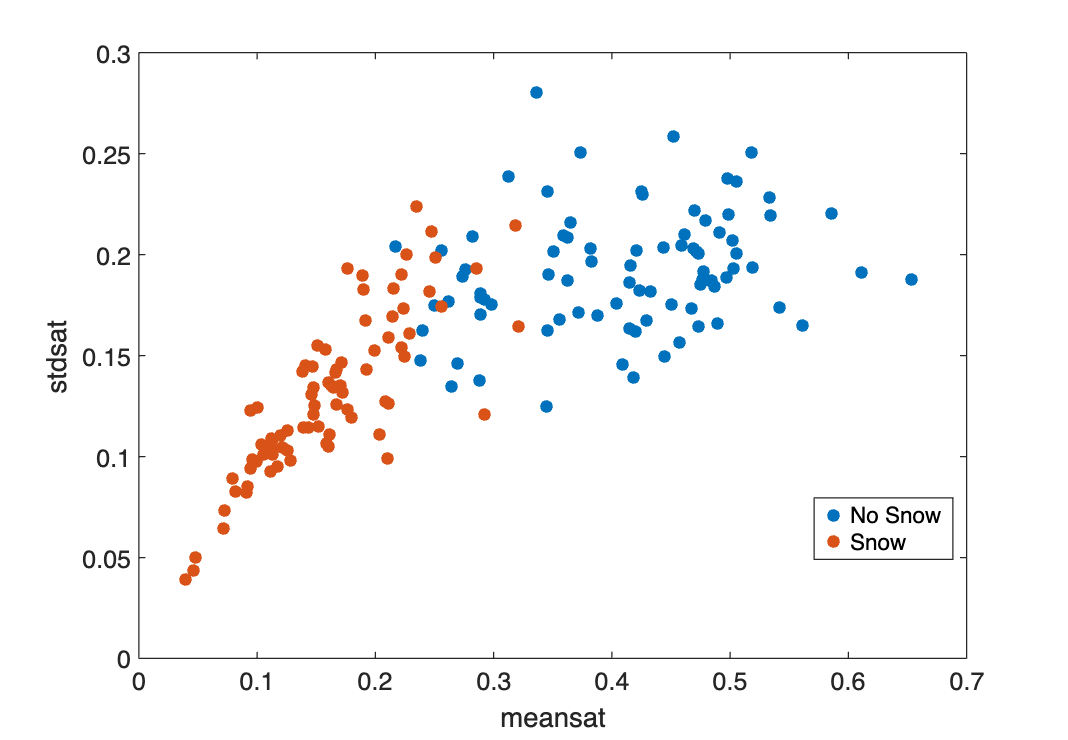

gscatter(meansat, stdsat, labels);

names = [];
meansat = [];
stdsat = [];
labels = [];

while hasdata(testDs)
    [img, info] = read(testDs);
    imghsv = rgb2hsv(img);
    imgsat = imghsv(:,:,2);
    
    [~,name,ext] = fileparts(info.Filename);
    names = [names; string(name) + string(ext)];
    meansat = [meansat; mean(imgsat(:))];
    stdsat = [stdsat; std(imgsat(:))];
end

labels = categorical(testDs.Labels);
testFeatTable = table(names, labels, meansat, stdsat);

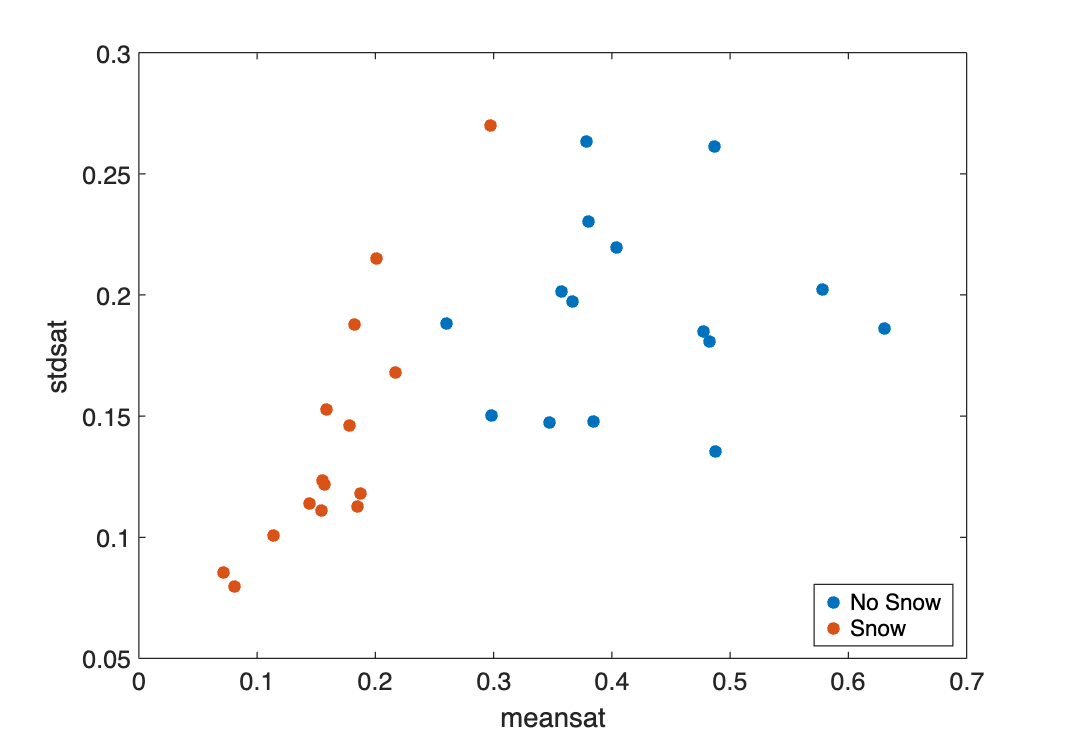

gscatter(meansat, stdsat, labels);